- VRE and PHS: Solar PV => large residual demand swing => PHS?

- VRE and Gas: VRE fast fluctuation => residual demand fluctuation => Gas?

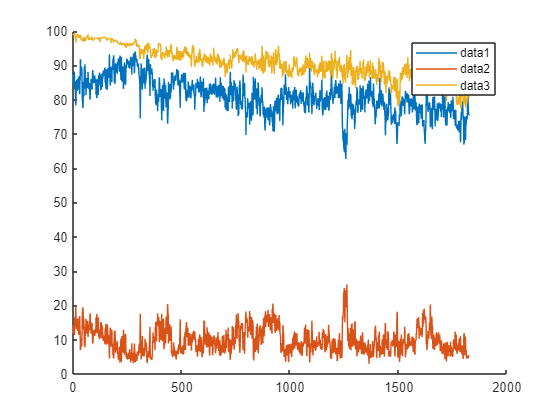

clf; hold on
plot(100*coalPcentDaily);
plot(100*gasPcentDaily);
plot(100*(coalPcentDaily+gasPcentDaily));
legend()

residualDemand = 1-solarPcent-windPcent;
% peakingGen = gasPcent+phsgenPcent;
peakingGen = phsgenPcent;
v1 = 100*diff(residualDemand);
v2 = 100*diff(peakingGen);

clf; hold on
h = height(v1); d = round(h/5);
% t1 = 1; t2 = d;
% corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
% scatter(v1(t1:t2),v2(t1:t2))
% t1 = d; t2 = d*2;
% corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
% scatter(v1(t1:t2),v2(t1:t2))
% t1 = d*2; t2 = d*3;
% corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
% scatter(v1(t1:t2),v2(t1:t2))
% t1 = d*3; t2 = d*4;
% corr(v1(t1:t2),v2(t1:t2),"type","Spearman")
% scatter(v1(t1:t2),v2(t1:t2))
t1 = d*4; t2 = h;
corr(v1(t1:t2),v2(t1:t2),"type","Spearman")

ans = 0.3937

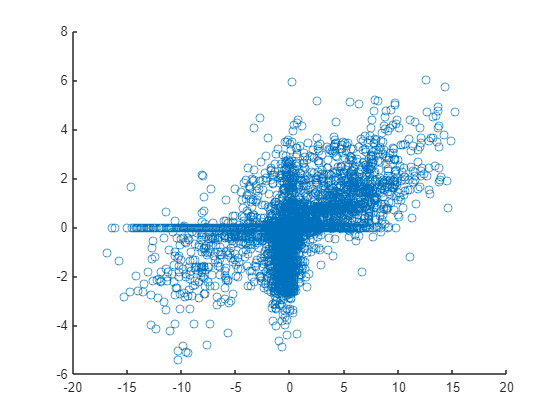

scatter(v1(t1:t2),v2(t1:t2))


% clf;
% scatter(v1,v2)
% corr(v1,v2,"type","Pearson")